# FEM of Full Electrodep Setup

## Introduction

This finite element analysis utilizes the MATLAB PDE ToolBox to examine potential gradients and electric flux across biocompatible conductive 3D scaffolds. An electrostatic analysis is performed on the geometry of the scaffold which is defined by material properties including the dielectric constant, charge density, and conductivity.

A voltage is applied to a face to simulate an electrical stimulation (ESTIM) across the geometry of the scaffold.

## Objective:

- Identify characteristic charge and energy distribution in common scaffold geometries

- Test different material properites 

- Model relationship between conductivity, flux, and charge injection

- Use this model to design experiment analysis

## Motivation

Develop an open source model to visulaize electrostatic performance of biomimetic soft polymer scaffolds, circuitry, and implantable devices.

Electrostatic analysis offers insight into the induced electrochemical and multiphasic conduction, current, and charge injection that is desired of bioactive conducting polymers

Utilizign Finite Element Analysis (FEA) gives a detailed mapping of localized charge, capacitive behavior, impedance behavior to characterize a material. The use of the MATLAB PDE ToolBox allows for simultatneous simulation with varying parameters. The goal is to guide the development of biomimetic systems that aim to test a variety of combinations of conductive properties, thermal, and mechanical stress.

FEA is a popular method by which partial differential equations PDE's that capture most physics  are solved numerically and mapped to a geometry.

## Overview of Analysis

##         Geometry

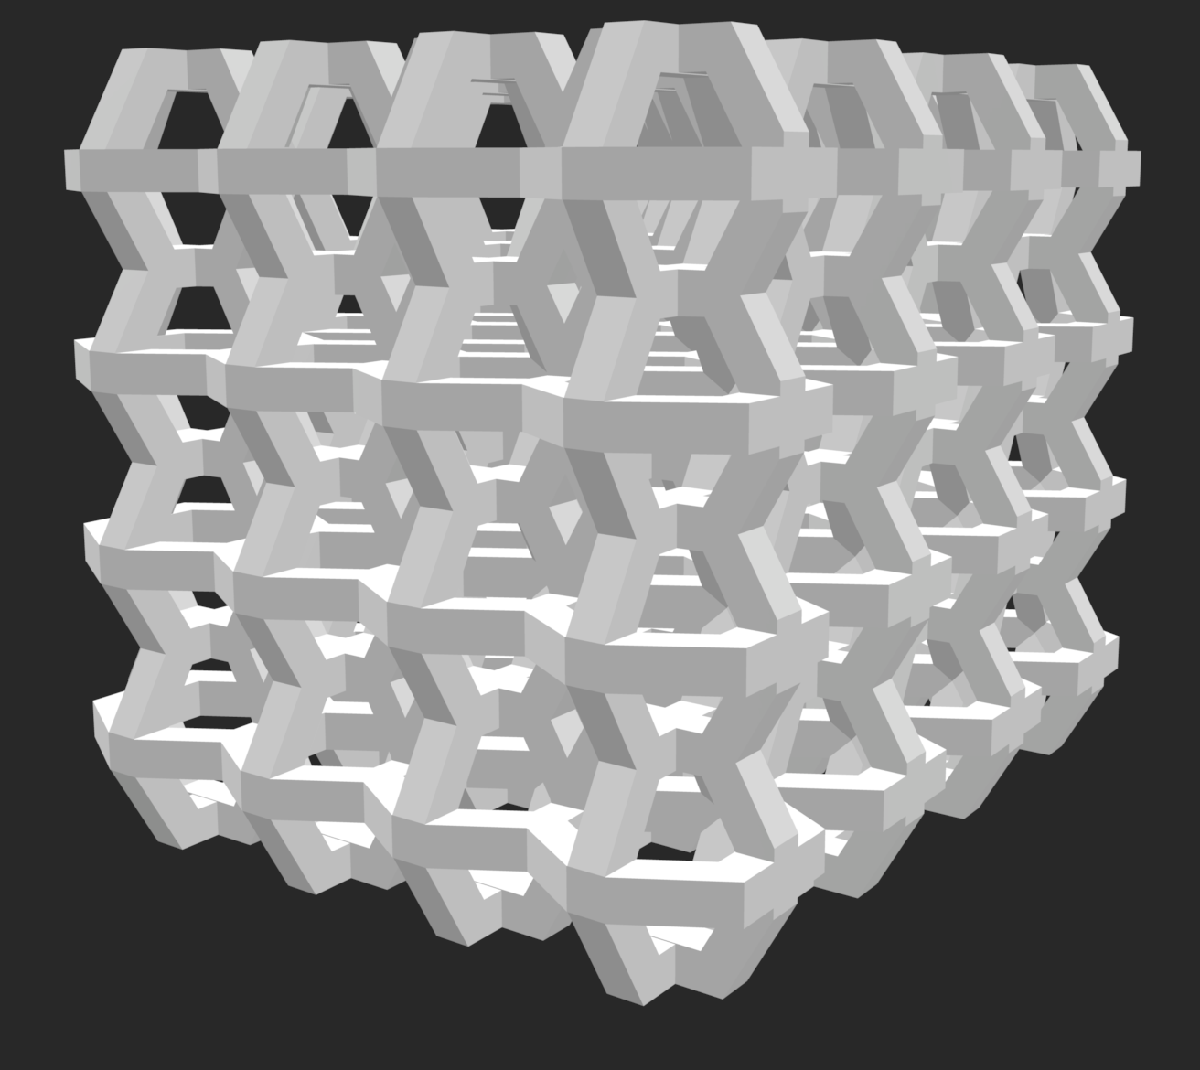

Figure 1: STL CAD of 3D hexagonal  scaffold geometry (pHEMA R.L. Keate, J. Tropp, A.J. Petty, G. Ameer, J. Rivnay)

##         Definition of Coefficients and BC

##         Charge Density

##         Material Properties

##         Meshing

## Import the Geometry

clear
clc
clf

Some paramaters are set in advance to simplify plotting

set(0,'DefaultAxesFontSize',15,'defaultaxeslinewidth',2,...
    'defaultlinelinewidth',5,'defaultpatchlinewidth',1.5)

The geometry is comprised of a conductive scaffold within a finite volume defined by a cube. This geometry is initialized and stored as gmAir. This is done first so that the geometry of the scaffold can fit inside the volume when it is then centered on the scaffold. 

gmAir = multicuboid(8,8,8);
gmAir.translate([2,2,-2]);

Here the scaffold geometry is imported by the name of the STL file. Ensure that this file is within the folder of this program. The imported geometry is then stored in the Scaffold variable and combined as cell into the model geometry gmModel. The geometry is then combined and defined as the electrostatics geometry of the model.

Scaffold = importGeometry('3D HEMA_Conductive Project_110um_small.stl');
%gmModel = addCell(gmAir,Scaffold);
gmModel = Scaffold;

The model is created and stored in the `E`stat_model variable

Estat_model = createpde('electromagnetic','electrostatic');
Estat_model.Geometry = gmModel;

We then plot the models to ensure that the correct geometry has been imported and that the volume around it is correctly centered. 

The geometry is also plotted with face labels and edge labels to identify planes and boundarys that will be injected with current, set with a voltage, or assigned insulative properties. 

figure
pdegplot(Estat_model,'FaceAlpha',0.1);

pdegplot(Estat_model,'FaceLabels','on','FaceAlpha',.3);

pdegplot(Estat_model,'CellLabels','on','FaceAlpha',.3);

The geometry has maximum feature sizes of 99 micro-meters  which we will round to 100 micro-meters and use as the standard length for the smallest features 

## Create the Mesh

From this we can understand create a mesh that has a maximum edge length of .1 micro-meters

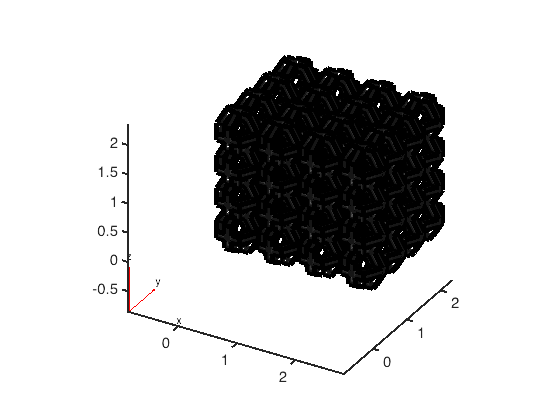

mesh = generateMesh(Estat_model, 'Hmax',.1);
Estat_model.Mesh

%elemsBushing = findElements(Estat_model.Mesh,"Region","Cell",2);



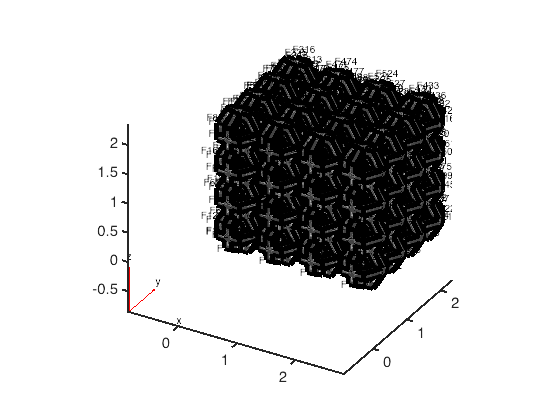

%pdemesh(Estat_model.Mesh.Elements(:,elemsBushing))
pdemesh(Estat_model,'FaceAlpha',.3)

The geometry undergoes final changes to split and identify objects as 'Cells' and select individual faces and edges of interest. In the case of simulating hydrogel scaffolds, it can be assumed that the faces making contact with the conducting plane  are of interest for initial parameters. These are identified in the plots and saved in a matrix. 

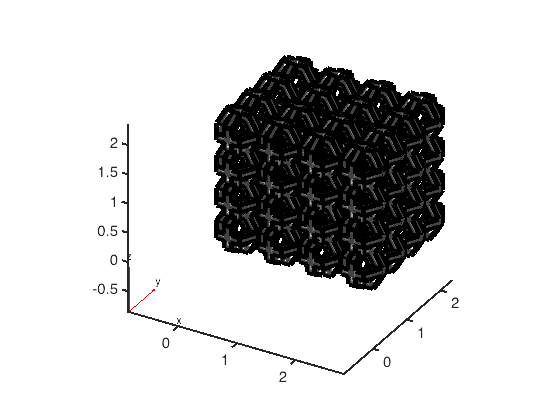

% Measuring the dimesions of the mesh
xLength = max(Estat_model.Mesh.Nodes(1,:)) - min(Estat_model.Mesh.Nodes(1,:))

yLength = max(Estat_model.Mesh.Nodes(2,:)) - min(Estat_model.Mesh.Nodes(2,:))
zLength = max(Estat_model.Mesh.Nodes(3,:)) - min(Estat_model.Mesh.Nodes(3,:))

%Splitting components


%HEMA 110 um scaffold

ans =   FEMesh with properties:

             Nodes: [3×146631 double]
          Elements: [10×72668 double]
    MaxElementSize: 0.1000
    MinElementSize: 0.0500
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


HEM_Bottom_Faces = [1328 1323 1345 1133 1293 1184 1189 1170 1143 ];


## Define Governing Equations and Parameters of the PDE

### Parameters

These parameters are defined to represent the characteristics of the electrolyte solution and the material properties

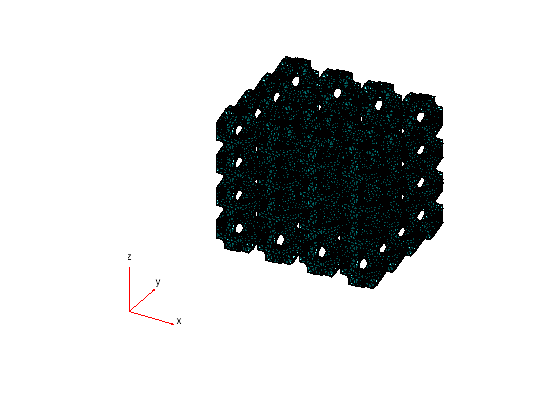

%Electrolyte
% Cation diffusion coefficient m2 s−1 (Sodium Na+)
catdiff = 1.33E-4;

% Anion diffusion coefficient  m2 s−1 (Chloride Cl-)
anndiff = 2.03E-4;
% Cation Valence
catval = +1;

xLength = 2.8298

% Anion Valence

yLength = 2.3375

anval = -1;

zLength = 2.3425

% Bound Charges
matval = nan;
% Temperature K
Temp = nan;
% Gas Constant J mol−1 K−1
Gas_Cons = nan;
% Faraday Constant C mol−1
Farad = 96485;
% Cation Mobility m2 s−1 V−1
catmobility = 4.98E-8;
% Anion Mobility m2 s−1 V−1
anmobility = 6.88E-8;
% Vacuum Permitivity AsV−1 m−1
vacuum_perm = 8.854E10-12;
% Relative Permitivity
relperm = 100;

##  Coupled Chemoelectrostatic PDE

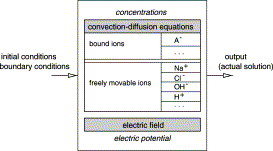

This coupled PDE solves the convection-difussion equatoin and Poisson equation simultaneasoly to calculate the electric potential. First it is assumed that the concentration of the electrolyte 

###     Define Governing Equation & Specify PDE Coefficients 

syms catcon(t,x,y,z)
syms Dcat Dan catz anz catmob anmob F epsr eps0

cat_pde = (1/(catdiff+catz*V))*diff(catcon,x,y);
%anion_pde = (1/(anndiff+anz*V))*diff(ancon,t);

A = -(F/(epsr*eps0));
voltag_pde = A*(catz*cat_pde)

%voltag_pde = @(region,state) [A*(catval*stat.catconc)

% symCoeffs = pdeCoefficients(Coupled_Voltage,V,'Symbolic',true)
% symVars = [Dcat Dan catz anz catmob anmob F epsr eps0]
% symVals = [catdiff anndiff catval anval catmobility anmobility Farad vacuum_perm relperm]
% symCoeffs = subs(symCoeffs,symVars,symVals);

coeffs = pdeCoefficientsToDouble(symCoeffs)
specifyCoefficients(model,'m',0,...
    'd',,...
    'c',0,...
    'a',0,...
    'f',voltag_pde);

% cation_conc = (D_cation*cation_conc)+(cation_val*cation_conc*cation_mobilit*Voltage)-(cation_conc*Voltage)+(cation_gen*speciesconc)
% anion_conc = (D_anion*anion_conc)+(anion_val*cation_conc*anion_mobilit*Voltage)-(anion_conc*Voltage)+(anion_gen*speciesconc)

%Coupled_Voltage = @(region,state) [-(F/(epsilon_r*epsilon_0))*((cation_val*cation_conc)+(anion_val*cation_conc))];

###      Define Initial Conditions

%coupled_f_ic = @(region); %%[Steady state equation]

%setInitialConditions(Estat_model,coupled_f_ic)

###      Establish Time Domain of Simulation 

tlist = linspace(0,2,10);

## Material Properties  

The materials of interest are the electrolyte medium or culture medium, scaffold polymer material and dopant, working electrode material.

%% Conversions

%%Vacuum
Estat_model.VacuumPermeability = 1.2566370614E-6;
Estat_model.VacuumPermittivity = 8.8541878128E-12;

%%Culture Medium
electromagneticProperties(Estat_model,"Cell",1,"RelativePermittivity",1);

Error using sym/pdeCoefficients
Cannot handle equations that are of first order.

% %%ITO
% electromagneticProperties(emagmodel,"RelativePermittivity",2.25, ...
%                                     "Face", ITO_Face)
% %%Electrodes
% electromagneticProperties(emagmodel,"RelativePermittivity",2.25, ...
%                                     "Face", ITO_Face)
%Scaffold
electromagneticProperties(Estat_model,"Cell",2,"RelativePermittivity",4.74)

## Boundary Conditions

In the pHEMA paper the conductivity of these scaffolds was tested using a custome ITO dual electrode setup. The boundary conditions of the faces that make contact with this electrode setup are set to be constant voltages.

## Charge Density

%Scaffold
electromagneticSource(Estat_model,"ChargeDensity",5E-10);

%% BC ITO
electromagneticBC(Estat_model,"Voltage",.075,"Face",HEM_Bottom_Faces)
%BC Scaffold
%electromagneticBC(Electrodep_model,"Voltage",0,"Face",3:6)
%BC Working
%BC Counter


**Specify Current Density**

## Solving the Model

emagmodel = Estat_model;
R = solve(emagmodel);


## Visualizing Model Results

model = emagmodel;

ans =   ElectromagneticBCAssignment with properties:

           RegionType: 'Face'
             RegionID: [1328 1323 1345 1133 1293 1184 1189 1170 1143]
              Voltage: 0.0750
    MagneticPotential: []
           Vectorized: 'off'


elemsBushing = findElements(model.Mesh,"Region","Cell",2);

pdeplot3D(model.Mesh.Nodes, ...
    model.Mesh.Elements(:,elemsBushing),"FlowData",[R.ElectricField.Ex ...
    R.ElectricField.Ey ...
    R.ElectricField.Ez],"ColorMapData",R.ElectricPotential,'Mesh','on')
title('Electric Field [V]')
xlabel('x')

ylabel('y')
zlabel('z')


pdeplot3D(emagmodel,"FlowData",[R.ElectricFluxDensity.Dx ...
    R.ElectricFluxDensity.Dy ...
    R.ElectricFluxDensity.Dz],'Mesh','on',"FaceAlpha", .5)
title('Flux Density')
xlabel('x')
ylabel('y')
zlabel('z')

pdeplot3D(model.Mesh.Nodes, ...
    model.Mesh.Elements(:,elemsBushing),"ColorMapData",R.ElectricPotential)
title('Electric Potential [V]')

Emag = sqrt(R.ElectricField.Ex.^2 + ...

    R.ElectricField.Ey.^2 + ...
    R.ElectricField.Ez.^2);
pdeplot3D(model.Mesh.Nodes, ...
    model.Mesh.Elements(:,elemsBushing), ...
    "ColorMapData",Emag);

axis equal
xlabel('x')
ylabel('y')

zlabel('z')

## Optional Parallel Parameter Sweep